# Tarea OSEP

#### Datos Generadores

Pmin    = [150 20 25 20 10];                        %MW
Pmax    = [455 130 162 130 55];                     %MW
a       = [1000 700 450 680 670];                   %$
b       = [16.19 16.6 19.7 16.5 27.8];              %$/MW
c       = [0.00048 0.002 0.00398 0.00211 0.00173];  %$/MW^2
t       = [8 5 6 5 1];                              %h
Cs      = [9000 1100 1800 1120 60];                 %$
Ramp    = [136.5 130 162 130 55];                   %MW/h
% Convertir a fila
Pmin = Pmin(:)'; 
Pmax = Pmax(:)'; 
a = a(:)';     
b = b(:)';       
c = c(:)';   

#### Demanda

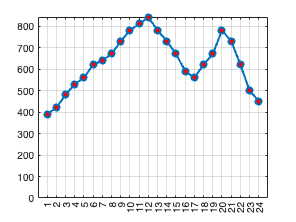

D       = [390 420 480 530 560 620 640 670 730 780 810 840 780 730 670 590 560 620 670 780 730 620 500 450];%MW  
D       = D';
graficarhoras(D)

#### Aero Generadores

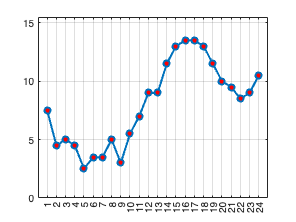

Vv      = [7.5 4.5 5 4.5 2.5 3.5 3.5 5 3 5.5 7 9 9 11.5 13 13.5 13.5 13 11.5 10 9.5 8.5 9 10.5];%m/s
graficarhoras(Vv)

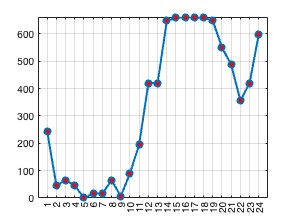

Vp      = [0 0; 0.5 0; 1 0; 1.5 0; 2 0; 2.5 0; 3 29; 3.5 81; 4 146; 4.5 226; 5 327; 5.5 452; 6 600; 6.5 775; 7 981; 7.5 1216; 8 1487; 8.5 1780; 9 2103; 9.5 2437; 10 2753; 10.5 2999; 11 3159; 11.5 3241; 12 3276; 12.5 3290; 13 3297; 13.5 3300]; %m/s kW
Vgen    = [];
for viento = 1:length(Vv)
    for relaciones = 1:size(Vp, 1)
        if Vv(viento) == Vp(relaciones, 1)
            Vgen(viento) = Vp(relaciones, 2);
        elseif Vv(viento) >= 13.5 && Vv(viento)<= 25
            Vgen(viento) = 3300;
        end
    end
end

Gvmax   = Vgen*200/1000;                             %MW
Gvmax   = Gvmax';
Gvmin   = zeros(num_horas, 1);
graficarhoras(Gvmax)

#### Optimización

####         Estado inicial

demanda_0 = D(1);
FO              = @(P) sum(a + b .* P + c .* (P.^2));
Aeq             = [1 1 1 1 1];
beq             = demanda_0;
A               = [];
b               = [];
x0              = [0 0 0 0 0];
x0              = x0(:)';

[V_o, f_0]      = fmincon(FO, x0, A, b, Aeq, beq, Pmin, Pmax);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


####     Restricciones

%Restricción de igualdad
num_generadores = 5;
num_horas       = 24;
P               = ones(num_horas, num_generadores + 1);
Pminv           = Pm_viento(num_horas, num_generadores + 1, Pmax, Gvmin)

Pminv =    455   130   162   130    55     0
   455   130   162   130    55     0
   455   130   162   130    55     0
   455   130   162   130    55     0
   455   130   162   130    55     0
   455   130   162   130    55     0
   455   130   162   130    55     0
   455   130   162   130    55     0
   455   130   162   130    55     0
   455   130   162   130    55     0


Pmaxv           = Pm_viento(num_horas, num_generadores + 1, Pmax, Gvmax)

Pmaxv =   455.0000  130.0000  162.0000  130.0000   55.0000  243.2000
  455.0000  130.0000  162.0000  130.0000   55.0000   45.2000
  455.0000  130.0000  162.0000  130.0000   55.0000   65.4000
  455.0000  130.0000  162.0000  130.0000   55.0000   45.2000
  455.0000  130.0000  162.0000  130.0000   55.0000         0
  455.0000  130.0000  162.0000  130.0000   55.0000   16.2000
  455.0000  130.0000  162.0000  130.0000   55.0000   16.2000
  455.0000  130.0000  162.0000  130.0000   55.0000   65.4000
  455.0000  130.0000  162.0000  130.0000   55.0000    5.8000
  455.0000  130.0000  162.0000  130.0000   55.0000   90.4000


S               = matriz(num_generadores, num_horas, 's');
U               = matriz(num_generadores, num_horas, 'u');  
for hora = 1:num_horas
    for gen = 1:num_generadores
        FO(gen, hora)    = Fc(gen)*U(gen, hora) + Cs(gen)*S(gen, hora);
    end
end

Unable to perform assignment because value of type 'sym' is not convertible to 'function_handle'.

Caused by:
    Error using function_handle
    Too many output arguments.

FO              = sum(FO(:))

[x_min, fval]   = fmincon(FO, V_o, A, b, P, D, Pminv, Pmaxv);
[x_min, fval]   = intlinprog(f, intcon, A, b, Aeq, beq, lb, ub)


function graficarhoras(Vv)
    horas = 1:24;
    figure;
    plot(horas, Vv, '-o', 'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor', 'r');
    grid on;
    % xlabel('Hora del día (h)');
    % ylabel('Velocidad del viento (m/s)');
    % title('Velocidad del viento durante las 24 horas');
    xticks(1:24); % Marcar todas las horas
    xlim([0 25]); % Ajustar límites del eje x
    ylim([0 max(Vv) + 2]); % Ajustar límites del eje y
end

function S = matriz(num_generadores, num_horas, letra)
    % Crear la matriz S de tamaño (num_generadores x num_horas) con variables simbólicas
    
    % Inicializar la matriz S
    S = sym(letra, [num_generadores, num_horas]);  % Matriz simbólica de tamaño especificado
    
    % Crear la matriz con el formato s_i_t
    for i = 1:num_generadores
        for t = 1:num_horas
            % Asignar nombre dinámico de la variable como s_i_t
            S(i, t) = sym([letra '_' num2str(i) '_' num2str(t)]);  % Asigna la variable simbólica
        end
    end
end
function matriz = Pm_viento(n, m, l, v)
    % Crear una matriz de nxm donde cada fila tiene los valores de l,
    % y la última columna es el valor correspondiente de v
    
    % Verificar que el tamaño del vector fila l sea igual a m-1
    if length(l) ~= m - 1
        error('El tamaño del vector l debe ser igual a m-1');
    end
    
    % Inicializar la matriz repitiendo el vector l en todas las filas
    matriz = repmat(l, n, 1);  % Repetir el vector l n veces por filas
    
    % Mantener el último valor de l en cada fila
    matriz(:, 1:end-1) = repmat(l(1:end-1), n, 1);  % Rellenar las columnas, excepto la última
    
    % Asignar los valores de v a la última columna
    matriz(:, end + 1) = v(1:n);  % Agregar v como la última columna
end

